# Comparing Actuator Rating of Parametric Robot and CAD Robot

This example compares the actuator maximum power and maximum torque of parametric robot with the same for an equivalent CAD geometry model.

Copyright 2023 - 2024 The MathWorks, Inc.

To return to the main page within this repository, [click here](matlab:web('RobotDesignOverview.html')).

## **Evaluate Actuator Rating for CAD Geometry Robot **

Setup the parameters and run script for actuator rating for CAD imported robot arm

modelRobot = 'sm_abbIrb120_1_RawImport';
modelName="ActuatorRatingModel";
endEffectorName = "Body5";
simTime = 3; % [s] simulation time for rating

load_system(modelName)
LoadCADRating; % Set the config model for CAD robot

Configuring the actuator rating model with Parametric robot...


Generate the volume sphere of the robot
Generate the envelope of front-view
Generate the boundary of front-view


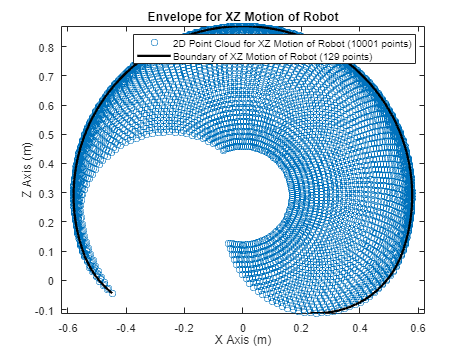

Generate the waypoints for front-view motion
Calculate the power consumed by each joint from the simulation of
Plot the measurements of the simulation of the front-view motion


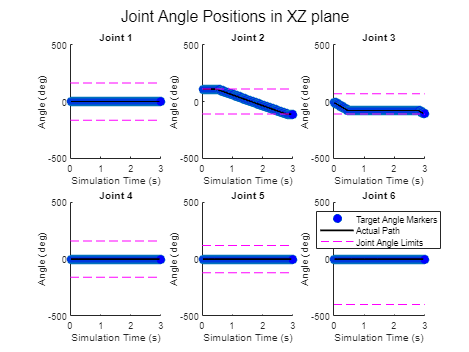

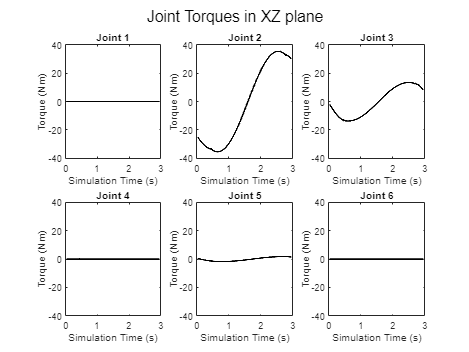

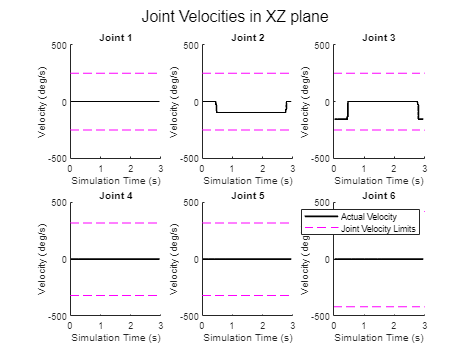

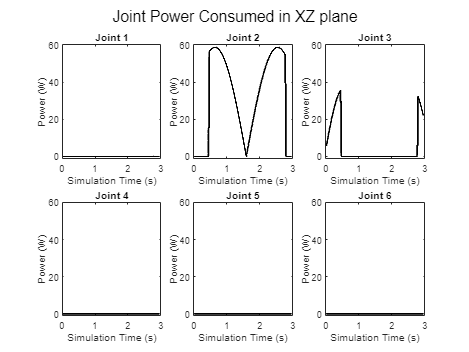

Generate the boundary of the top-view


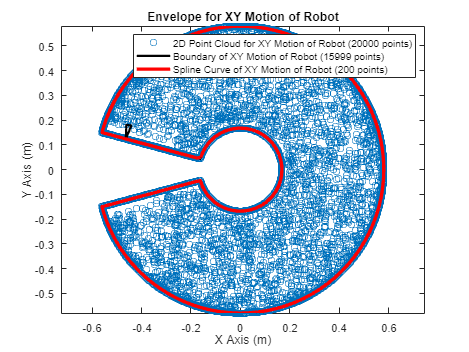

Simulate the top-view motion


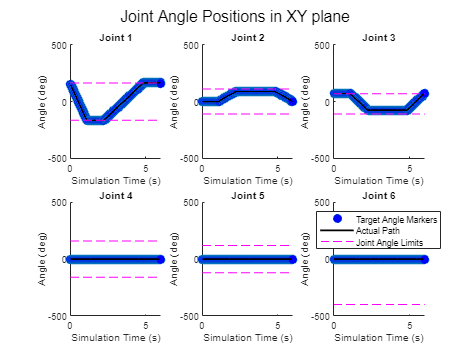

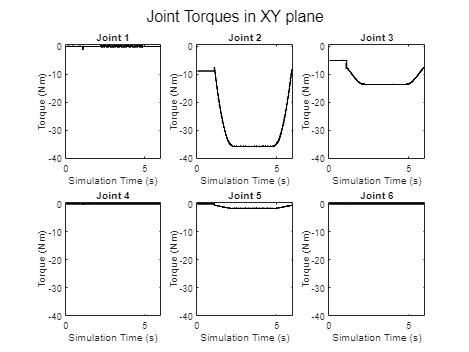

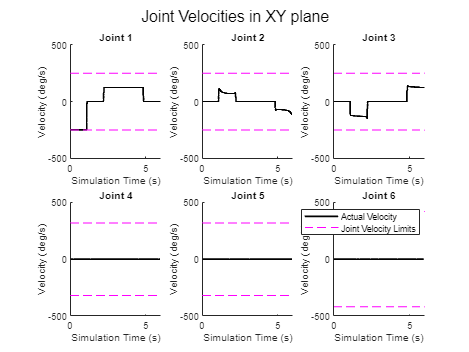

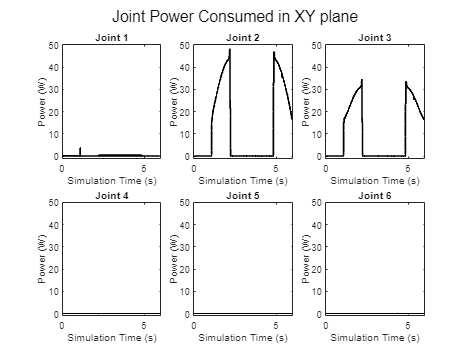

roboticArmEnvelopeAndRating(modelRobot,modelName,endEffectorName,simTime)

close_system(modelName,0)

## Compare Ratings of Parametric Robot with CAD Robot

A comparison of the CAD geometry robot actuator and equivalent parametric robot for the base, shoulder and elbow joint is shown in the below table.

Load parametric table data from pre-recorded mat file or you can run the [actuator rating workflow](matlab:open('ActuatorRatingWorkflow.mlx')) to generate the data.

tableParametric = tableActuatorRating('ratingsFrontParametricRobotModel.mat','ratingsTopParametricRobotModel.mat');

Load CAD actuator data from the model run for comparison.`

tableCAD = tableActuatorRating('ratingsFrontsm_abbIrb120_1_RawImport.mat','ratingsTopsm_abbIrb120_1_RawImport.mat');

% Comparison table for max torque and max power for base, shoulder and
% elbow joints
actuatorDataTable = array2table([tableCAD.joint ,tableParametric.torque, tableCAD.torque, tableParametric.power, tableCAD.power],...
           'VariableNames',{'Joint','Max Torque PAR (Nm)','Max Torque CAD (Nm)','Max Power PAR (W)','Max Power CAD (W)'} )

actuatorDataTable = 3×5 table
      Joint      Max Torque PAR (Nm)    Max Torque CAD (Nm)    Max Power PAR (W)    Max Power CAD (W)
    _________    ___________________    ___________________    _________________    _________________

    "Joint 1"         "1.17213"              "1.07383"             "4.02354"            "3.51445"    
    "Joint 2"         "35.2308"              "35.5235"             "58.1508"            "58.6674"    
    "Joint 3"         "13.2769"              "13.5776"             "34.8314"            "35.5756"    


## Useful Link

For more detail on actuator rating , see [ActuatorRatingWorkflow](matlab:open('ActuatorRatingWorkflow.mlx')).